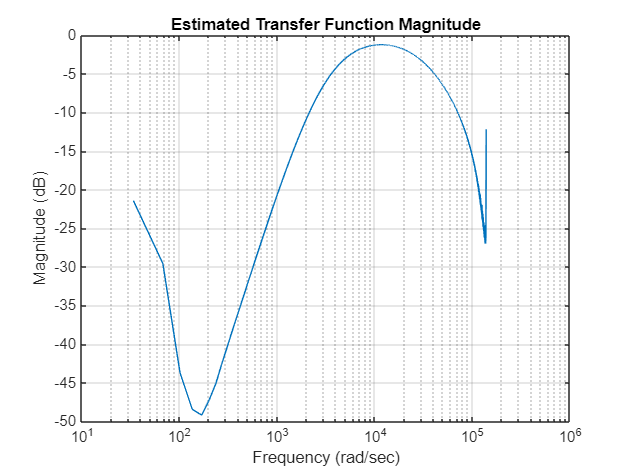

load ProjectData2.mat

% Attained powr spectrum of Original and Distoried souns
NFFT = 1024*8; % FFT Size
OL = 50; % Overlap percentage
[Pxx,F] = pwelch(X, [], OL,NFFT,Fs);% Power spectra of X (Original Sound)
[Pyy,~] = pwelch(Y,[], OL, NFFT, Fs); % Power spectra of Y (Distorted Sound)

% Calculated Transfer Function Magnitude
H = sqrt(Pyy ./ Pxx);

figure;
semilogx(2*pi* F, 20*log10(H));  % Plot in dB scale
xlabel('Frequency (rad/sec)');
ylabel('Magnitude (dB)');
title('Estimated Transfer Function Magnitude');
grid on;

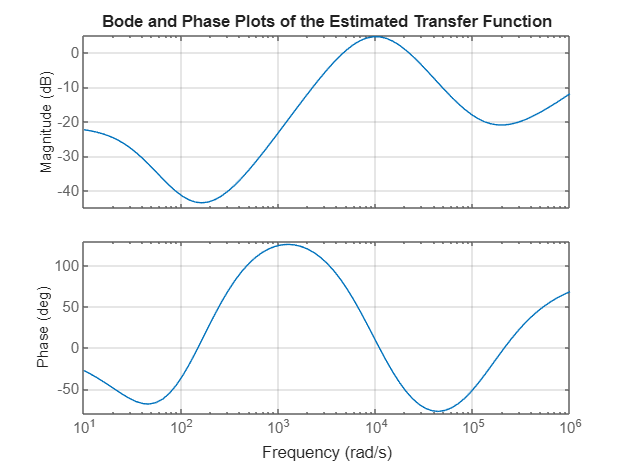


s = tf('s'); % trasnfer function routine
k = 2.46247*10^-7; % Estimated constant for transfer function
H_est = (k)*(((s+140)^5)*((s+140000)^3))/(((s+35)^3)*((s+10000)^4)); % Estimated transfer function
% Plotted Bode and Phase plots of H_est
figure;
bode(H_est, {10, 1000000});
title('Bode and Phase Plots of the Estimated Transfer Function');
grid on;

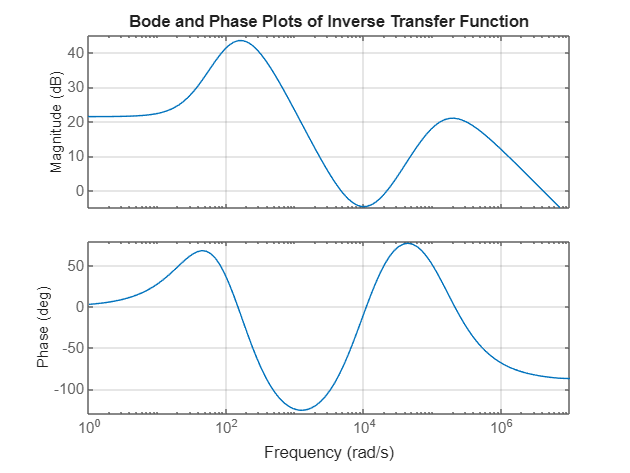


% Inverse transfer function
H_inv = 1/H_est;  

% Plotted Bode and Phase plots of the inverse transfer function
figure;
bode(H_inv);
title('Bode and Phase Plots of Inverse Transfer Function');
grid on;

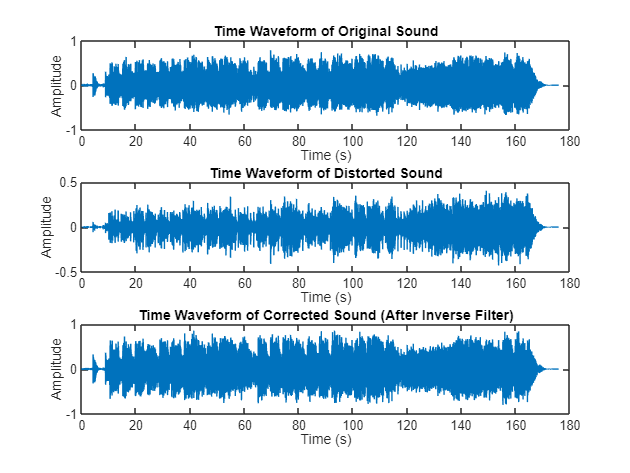


T = (0:length(Y)-1)/Fs; % Time Vector
Y_corrected = lsim(H_inv, Y, T); % simulated inverse filter with distored sound


% Time Waveform Plots of original, distorted and corected sounds
figure;
subplot(3,1,1);
plot(T, X);
title('Time Waveform of Original Sound');
xlabel('Time (s)');
ylabel('Amplitude');

subplot(3,1,2);
plot(T, Y);
title('Time Waveform of Distorted Sound');
xlabel('Time (s)');
ylabel('Amplitude');

subplot(3,1,3);
plot(T, Y_corrected);
title('Time Waveform of Corrected Sound (After Inverse Filter)');
xlabel('Time (s)');
ylabel('Amplitude');

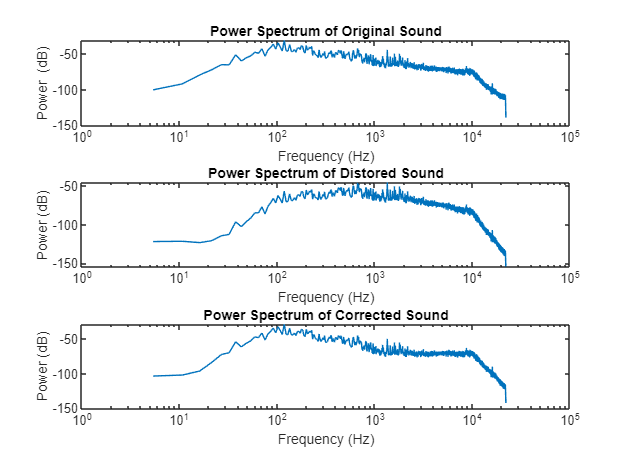



% Power spectrum of the original, distorted, and corrected signals
figure;
subplot(3,1,1);
semilogx(F, 10*log10(pwelch(X, [], OL, NFFT, Fs)));
title('Power Spectrum of Original Sound');
xlabel('Frequency (Hz)');
ylabel('Power  (dB)');

subplot(3,1,2);
semilogx(F, 10*log10(pwelch(Y, [], OL, NFFT, Fs)));
title('Power Spectrum of Distored Sound');
xlabel('Frequency (Hz)');
ylabel('Power (dB)');

subplot(3,1,3);
semilogx(F, 10*log10(pwelch(Y_corrected, [], OL, NFFT, Fs)));
title('Power Spectrum of Corrected Sound');
xlabel('Frequency (Hz)');
ylabel('Power (dB)');

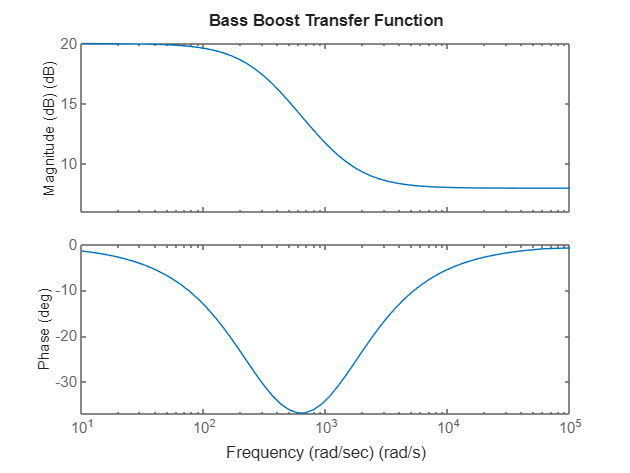


figure;
% Bass Boost
omega1 = 2*pi*50; omega2 = 2*pi*200; % Bass Boost
H_bass = 10 * (s/omega2 +1)/ (s/omega1 +1);
bode(H_bass);
xlabel('Frequency (rad/sec)');
ylabel('Magnitude (dB)');
title('Bass Boost Transfer Function');

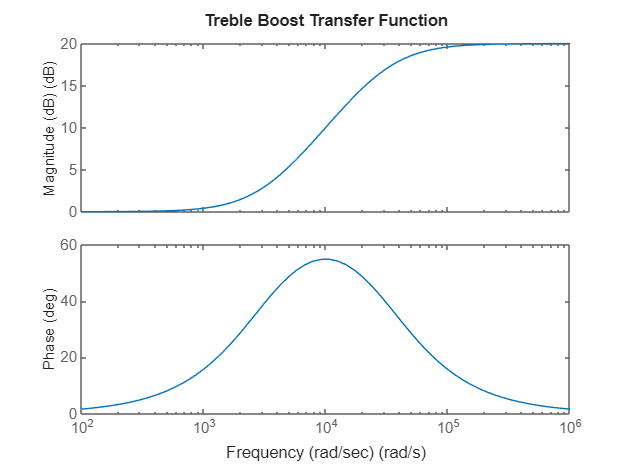


figure;
% Treble Boost
omega3 = 2*pi*500; omega4 = 2*pi*5000; % Treble Boost
H_treble = (s/omega3 +1)/ (s/omega4 +1);
bode(H_treble);
xlabel('Frequency (rad/sec)');
ylabel('Magnitude (dB)');
title('Treble Boost Transfer Function');

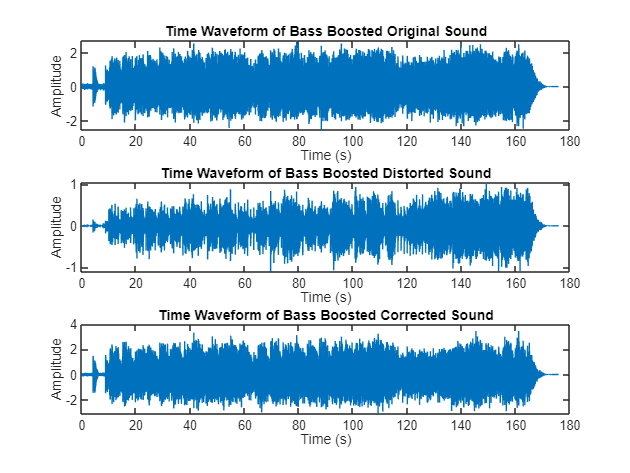


% Applied Bass Boost to original sound
X_bass_boosted = lsim(H_bass, X, T);

% Applied Treble Boost to original sound
X_treble_boosted = lsim(H_treble,X,T);


% Applied Bass boost to distored sound
Y_bass_boosted = lsim(H_bass, Y, T);

% Applied Treble Boost to distored sound
Y_treble_boosted = lsim(H_treble, Y, T);


% Applied Bass boost to corrected sound
Y_corrected_bass_boosted = lsim(H_bass, Y_corrected, T);


% Applied Treble Boost to corrected sound

Y_corrected_treble_boosted = lsim(H_treble, Y_corrected, T);


% Time domain waveform of bass boosted sound
figure;
subplot(3,1,1);
plot(T, X_bass_boosted);
title('Time Waveform of Bass Boosted Original Sound');
xlabel('Time (s)');
ylabel('Amplitude');

% Time domain waveform of distorted sound with Bass boost
subplot(3,1,2);
plot(T, Y_bass_boosted);
title('Time Waveform of Bass Boosted Distorted Sound');
xlabel('Time (s)');
ylabel('Amplitude');

% Time domain waveform of corrected sound with Bass boost
subplot(3,1,3);
plot(T, Y_corrected_bass_boosted);
title('Time Waveform of Bass Boosted Corrected Sound');
xlabel('Time (s)');
ylabel('Amplitude');

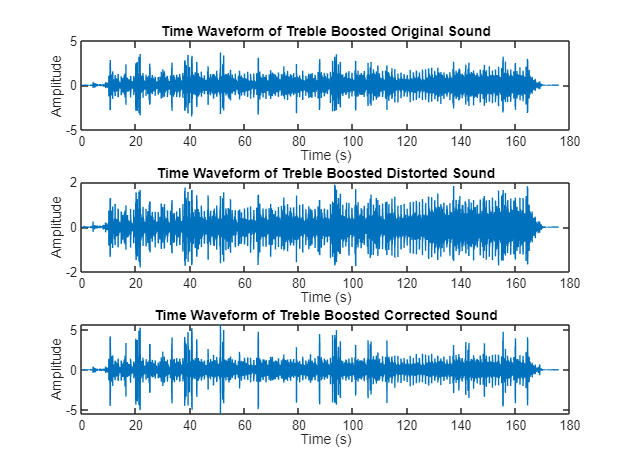




% Time domain waveform of treble boosted sound
figure;
subplot(3,1,1);
plot(T, X_treble_boosted);
title('Time Waveform of Treble Boosted Original Sound');
xlabel('Time (s)');
ylabel('Amplitude');

% Time domain waveform of distorted sound with Treble boost
subplot(3,1,2);
plot(T, Y_treble_boosted);
title('Time Waveform of Treble Boosted Distorted Sound');
xlabel('Time (s)');
ylabel('Amplitude');

% Time domain waveform of corrected sound with Treble boost
subplot(3,1,3);
plot(T, Y_corrected_treble_boosted);
title('Time Waveform of Treble Boosted Corrected Sound');
xlabel('Time (s)');
ylabel('Amplitude');

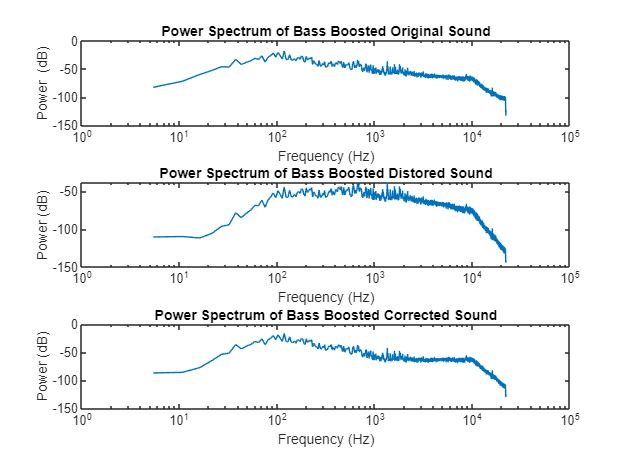


% Power spectrum of the bass boosted version of the original, distorted, and corrected signals
figure;
subplot(3,1,1);
semilogx(F, 10*log10(pwelch(X_bass_boosted, [], OL, NFFT, Fs)));
title('Power Spectrum of Bass Boosted Original Sound');
xlabel('Frequency (Hz)');
ylabel('Power  (dB)');

subplot(3,1,2);
semilogx(F, 10*log10(pwelch(Y_bass_boosted, [], OL, NFFT, Fs)));
title('Power Spectrum of Bass Boosted Distored Sound');
xlabel('Frequency (Hz)');
ylabel('Power (dB)');

subplot(3,1,3);
semilogx(F, 10*log10(pwelch(Y_corrected_bass_boosted, [], OL, NFFT, Fs)));
title('Power Spectrum of Bass Boosted Corrected Sound');
xlabel('Frequency (Hz)');
ylabel('Power (dB)');

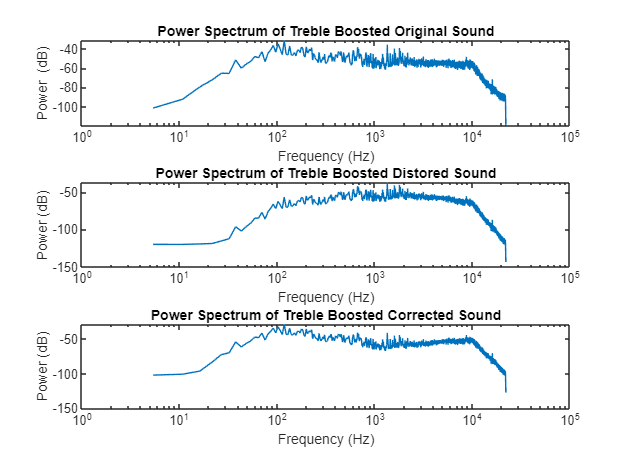



% Power spectrum of the treble boosted version of the original, distorted, and corrected signals
figure;
subplot(3,1,1);
semilogx(F, 10*log10(pwelch(X_treble_boosted, [], OL, NFFT, Fs)));
title('Power Spectrum of Treble Boosted Original Sound');
xlabel('Frequency (Hz)');
ylabel('Power  (dB)');

subplot(3,1,2);
semilogx(F, 10*log10(pwelch(Y_treble_boosted, [], OL, NFFT, Fs)));
title('Power Spectrum of Treble Boosted Distored Sound');
xlabel('Frequency (Hz)');
ylabel('Power (dB)');

subplot(3,1,3);
semilogx(F, 10*log10(pwelch(Y_corrected_treble_boosted, [], OL, NFFT, Fs)));
title('Power Spectrum of Treble Boosted Corrected Sound');
xlabel('Frequency (Hz)');
ylabel('Power (dB)');

nbits = 16; % number of bits

% Saved corrected sound
 audiowrite('corrected_sound.wav', Y_corrected/max(abs(Y_corrected)), Fs,'BitsPerSample', nbits);

 % Saved corrected sound with Bass Boost
 audiowrite('corrected_sound_bass_boosted.wav', Y_corrected_bass_boosted/max(abs(Y_corrected_bass_boosted)), Fs, 'BitsPerSample', nbits);

% saved corrected sound with Treble Boost
 audiowrite('corrected_sound_treble_boosted.wav', Y_corrected_treble_boosted/max(abs(Y_corrected_treble_boosted)), Fs, 'BitsPerSample', nbits);

% saved original input sound
 audiowrite('original_input_sound.wav', X/max(abs(X)), Fs, 'BitsPerSample', nbits);

 % Saved original sound with Bass Boost
 audiowrite('original_sound_bass_boosted.wav', X_bass_boosted/max(abs(X_bass_boosted)), Fs, 'BitsPerSample', nbits);

% saved original sound with Treble Boost
 audiowrite('original_sound_treble_boosted.wav', X_treble_boosted/max(abs(X_treble_boosted)), Fs, 'BitsPerSample', nbits);

% saved original output sound
 audiowrite('distorted_output.wav', Y/max(abs(Y)), Fs, 'BitsPerSample', nbits);

 % Saved original sound with Bass Boost
 audiowrite('distorted_sound_bass_boosted.wav', Y_bass_boosted/max(abs(Y_bass_boosted)), Fs, 'BitsPerSample', nbits);

% saved original sound with Treble Boost
 audiowrite('distorted_sound_treble_boosted.wav', Y_treble_boosted/max(abs(Y_treble_boosted)), Fs, 'BitsPerSample', nbits);


